clc;
clear;
s = tf("s");
freq = 1 / 20e-3; % F = 50Hz / T = 20ms
freq_amostragem = 5000; % Fs = 5000Hz / Ts = 0.2ms
T = 1/freq;
Ts = 1/freq_amostragem;

### Conversor Buck

Componentes foram pegos conforme a disponibilidade na sala de apoio, sempre tentando pegar o valor mais próximo do calculado

`| Componente | Valor Calculado |     Valor Real    |`

`|------------|-----------------|-------------------|`

`|     R      |       12Ω       |   15Ω -> 15.4Ω    |`

`|     L      |      3.44mH     |      3.3mH        |`

`|     C      |      `29.47uF           |        33uF -> 30.17uF          |

% =============== Conversor Buck - Calculado ===============
R = 12;
L = 3.44e-3;
C = 29.47e-6;

zeta = (1/(2*R)) * sqrt(L/C);
omega = 1 / sqrt(L * C);

Buck_calc = omega^2 / (s^2 + (2*zeta*omega)*s + omega^2)


Buck_calc =
 
         9.864e06
  -----------------------
  s^2 + 2828 s + 9.864e06
 
Continuous-time transfer function.
Model Properties



f_lc_calc = (1 / sqrt(L * C)) / (2 * pi)

f_lc_calc = 499.8628


% =============== Conversor Buck - Real ===============
R = 15.4;
L = 3.3e-3;
C = 30.17e-6;

zeta = (1/(2*R)) * sqrt(L/C);
omega = 1 / sqrt(L * C);

Buck_real = omega^2 / (s^2 + (2*zeta*omega)*s + omega^2)


Buck_real =
 
         1.004e07
  -----------------------
  s^2 + 2152 s + 1.004e07
 
Continuous-time transfer function.
Model Properties


Buck_real_discret = c2d(Buck_real, Ts, 'zoh')


Buck_real_discret =
 
    0.1693 z + 0.1464
  ----------------------
  z^2 - 1.334 z + 0.6502
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


f_lc_real = (1 / sqrt(L * C)) / (2 * pi)

f_lc_real = 504.4005

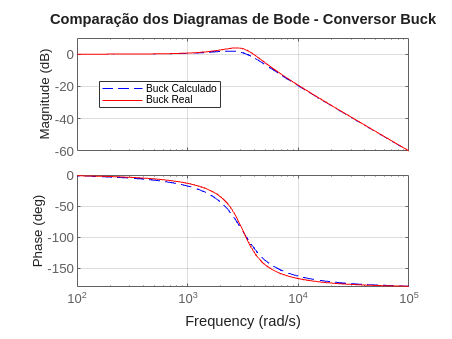


% =============== Comparação ===============
figure;
bode(Buck_calc, 'b--', Buck_real, 'r');
grid on;
legend('Buck Calculado', 'Buck Real', 'Location', 'best');
title('Comparação dos Diagramas de Bode - Conversor Buck');

O filtro anti-alising tera que ser reprojetado devido ao nosso f_lc com os componentes reais ter sido maior que a com o f_lc calculado com base nos componentes calculados

disp("=============== Filtro anti aliasing ===============")

=============== Filtro anti aliasing ===============


alpha = 0.5; % escolher entre 0.5 < alpha < 1
f_PB = alpha * sqrt(freq_amostragem * f_lc_real)

f_PB = 794.0407

omega_PB = 2 * pi * f_PB;  % em rad/s

zeta_PB = 0.3; % escolher entre 0.1 <= zeta <= 0.4
G_filtro_antialising = (omega_PB)^2 / (s^2 + 2*zeta_PB*omega_PB*s + omega_PB^2)


G_filtro_antialising =
 
         2.489e07
  -----------------------
  s^2 + 2993 s + 2.489e07
 
Continuous-time transfer function.
Model Properties


G_filtro_antialising_discret = c2d(G_filtro_antialising, Ts, 'zoh')


G_filtro_antialising_discret =
 
      0.38 z + 0.3093
  -----------------------
  z^2 - 0.8602 z + 0.5495
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


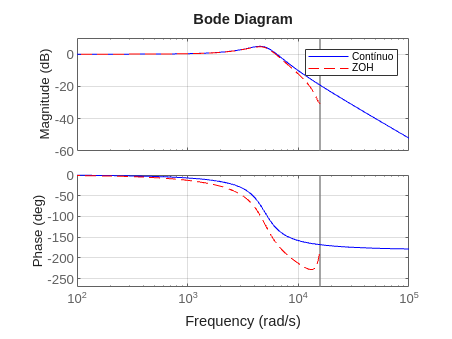


bode(G_filtro_antialising, 'b', G_filtro_antialising_discret, 'r--');
legend('Contínuo', 'ZOH');
grid on;

R1 = 10e3;
C1 = 1e-6;
syms R2 C2
eq1 = 2*zeta_PB*omega_PB == (1/(R2*C1)) + (1/(R1*C1));
eq2 = omega_PB^2 == (1 / (R1*C1*R2*C2));

sol = solve([eq1, eq2], [R2, C2]);
R2_val = double(sol.R2);
C2_val = double(sol.C2);

disp('Solução:');

Solução:


disp(['R1 = ', num2str(R1), 'Ω']);

R1 = 10000Ω


disp(['R2 = ', num2str(R2_val), 'Ω']);

R2 = 345.6066Ω


disp(['C1 = ', num2str(C1), ' F']);

C1 = 1e-06 F


disp(['C2 = ', num2str(C2_val), ' F']);

C2 = 1.1624e-08 F



disp("=============== Interação entre o Buck e o Filtro anti aliasing ===============")

=============== Interação entre o Buck e o Filtro anti aliasing ===============


G_i = Buck_real * G_filtro_antialising


G_i =
 
                        2.5e14
  ---------------------------------------------------
  s^4 + 5146 s^3 + 4.138e07 s^2 + 8.364e10 s + 2.5e14
 
Continuous-time transfer function.
Model Properties


G_i_discret = Buck_real_discret * G_filtro_antialising_discret


G_i_discret =
 
         0.06434 z^2 + 0.108 z + 0.04529
  ----------------------------------------------
  z^4 - 2.195 z^3 + 2.348 z^2 - 1.293 z + 0.3573
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


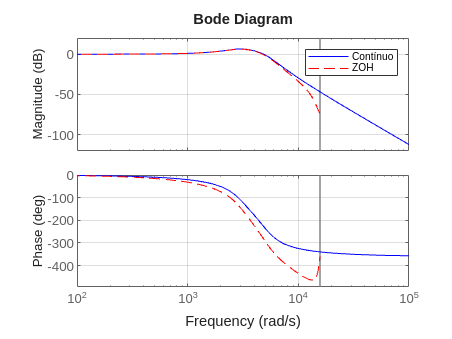


bode(G_i, 'b', G_i_discret, 'r--');
legend('Contínuo', 'ZOH');
grid on;

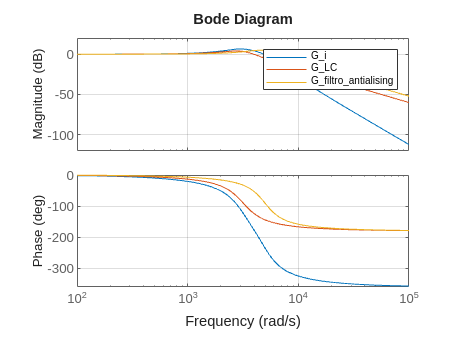


bode(G_i, Buck_real, G_filtro_antialising);
legend('G_i', 'G_LC', 'G_filtro_antialising');
grid on;